# Using and Comparing Pre-Trained Models

Many models created by experts and trained on extensive, general-purpose datasets are available in MATLAB. These models vary in size and complexity, often resulting in variations in accuracy and prediction speed.

In this reading, you will compare two pre-trained models:

- ResNet-18

- ResNet-50

The number in the network names (18 and 50) refers to the number of convolutional layers in each network, with ResNet-50 more than twice the size of ResNet-18.

## Installing and Viewing Networks in the Deep Network Designer App

The below code will launch the Deep Network Designer App. Use the app to open ResNet-18 and ResNet-50.

if isMATLABReleaseOlderThan("R2024a")
    deepNetworkDesigner
else
    deepNetworkDesigner -v1
end

The first time you open a network, you may have to install it by clicking the "Install" button:

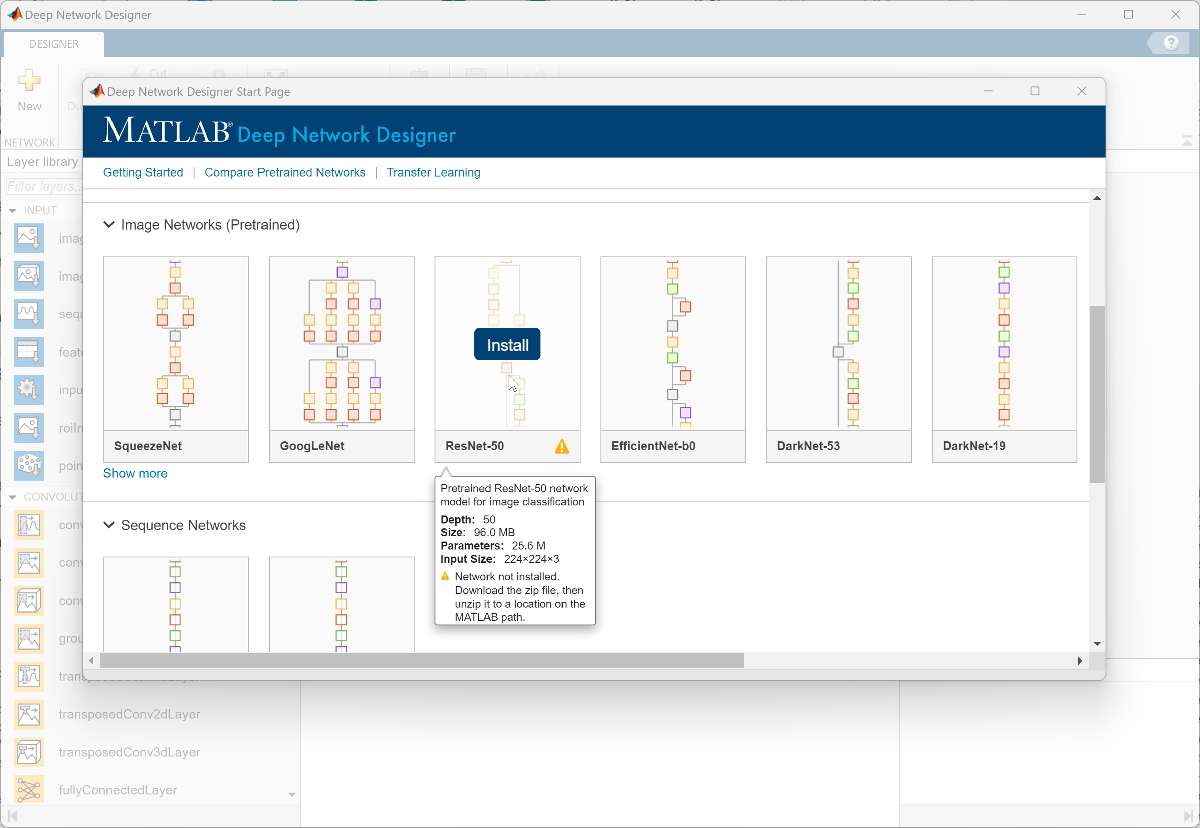

Consider the relative sizes of ResNet-18 and ReNet-50. Which has more layers? What layers do they share? 

## Loading Networks with Code

In addition to viewing pre-trained models in the Deep Network Designer app, you can also load installed models into the workspace using code:

net18 = resnet18;
net50 = resnet50;

**Note:** If you encounter an error during this step, you likely need to return to the previous step and install the model.

### Compare Model Sizes

The number of layers in a network greatly impacts the number of learnable parameters and model size. Extra complexity results in a larger model and slower prediction speeds but can give more accurate results in some applications.

Run this code to compare your models' sizes. 

whos net18 net50

  Name       Size                Bytes  Class         Attributes

  net18      1x1              47195761  DAGNetwork              
  net50      1x1             104595006  DAGNetwork              



## Accessing Network Layers

Each of these networks is a `DAGNetwork` object. It contains several pieces of information, primarily:

- `Layers`, an object containing the network layers

- `Connections`, a table describing how the layers interact. In more complex models, the layers are not connected linearly:

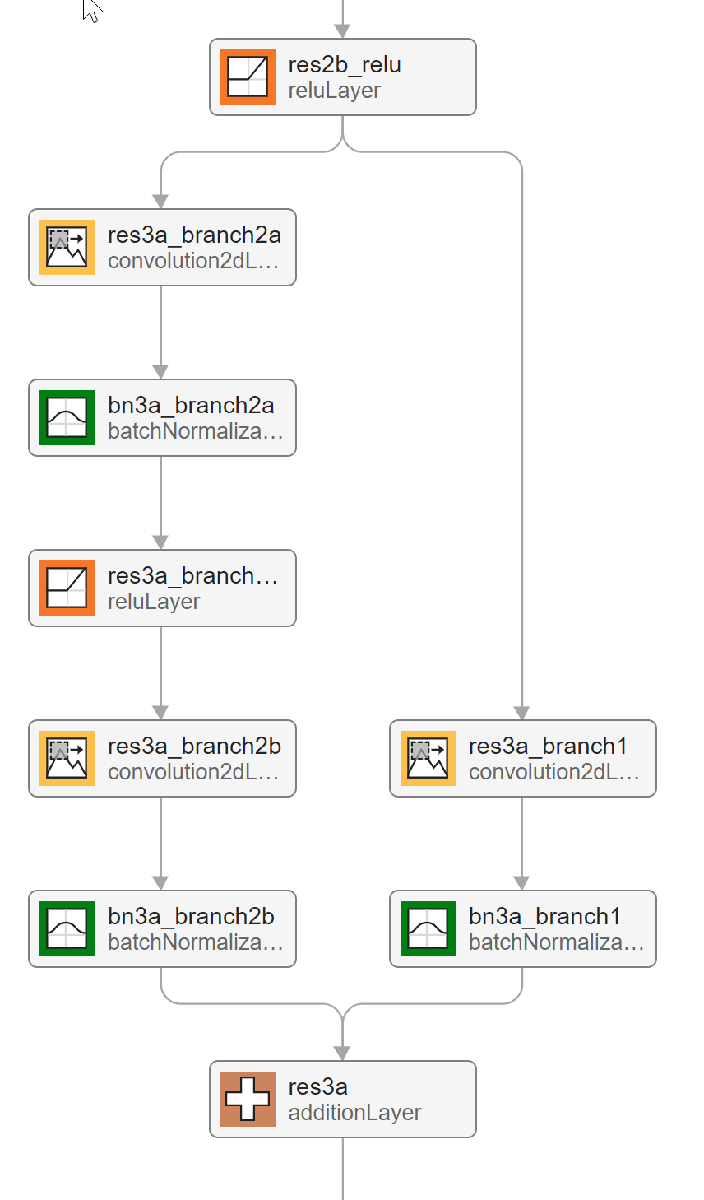

You can access the network layer details using dot notation. For example, the first layer is the input layer:

net18.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zscore'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]
         StandardDeviation: [1×1×3 single]


The last few layers of a classification network are generally the full-connected, softMax, and classification layers:

net18.Layers(end-2)

ans =   FullyConnectedLayer with properties:

          Name: 'fc1000'

   Hyperparameters
     InputSize: 512
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×512 single]
          Bias: [1000×1 single]

  Show all properties


net18.Layers(end-1)

ans =   SoftmaxLayer with properties:

    Name: 'prob'


net18.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_predictions'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


### Determining Network Complexity

The number of layers is also a good metric of a given network's complexity. How many more layers does ResNet-50 have than ResNet-18?

length(net18.Layers)

ans = 71

length(net50.Layers)

ans = 177

### Determining Image Input Size 

You can also explore layer-specific properties of the network. For example, you can determine each network's expected image input size:

net18.Layers(1).InputSize

ans =    224   224     3


net50.Layers(1).InputSize

ans =    224   224     3


Because these networks have the same `InputSize`, we only need to resize images once to use them in both networks.

## Using Pre-Trained Networks to Classify Images

Now that we know the image input size, make a prediction for the same image from the fastener dataset with both networks and compare the results. The `tic` and `toc` functions are used to compare prediction speeds.

Read in and resize the image:

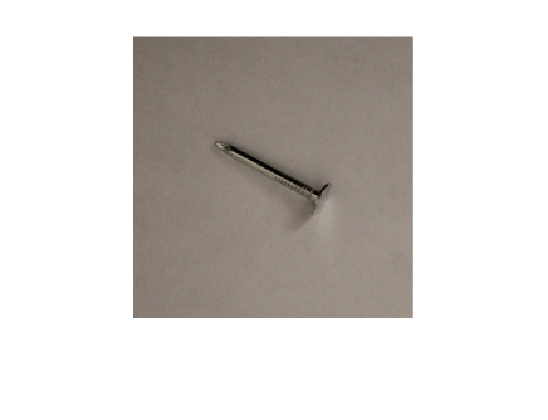

imgNail = imread("fastener0506.jpg");
imgNail = imresize(imgNail,[224,224]);
imshow(imgNail)

Make predictions for this image using the `classify` function:

tStart = tic;
prediction18 = classify(net18,imgNail);
tElapsed = toc(tStart);
results18 = "ResNet-18 prediction: " + string(prediction18) + newline + "ResNet-18 Prediction time: " + round(tElapsed,2) + " seconds"

results18 =     "ResNet-18 prediction: nail
     ResNet-18 Prediction time: 0.03 seconds"



tStart = tic;
prediction50 = classify(net50,imgNail);
tElapsed = toc(tStart);
results50 = "ResNet-50 prediction: " + string(prediction50) + newline + "ResNet-50 Prediction time: " + round(tElapsed,2) + " seconds"

results50 =     "ResNet-50 prediction: nail
     ResNet-50 Prediction time: 0.04 seconds"


How did each model perform? Which network had a faster prediction speed? 

The differences might seem small here, but remember that many applications require predictions for thousands of images. Those fractions of seconds add up quickly!

Feel free to install and try out different pre-trained models. A description of pre-trained classification models available in MATLAB can be found [here](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html). You may notice that pre-trained models often successfully identify a broad, general class. However, you'll soon see how to re-train them for tailored categories, such as identifying this nail as a $1\frac{1}{4}$ inch roofing nail.

*Copyright 2024 The MathWorks, Inc.*